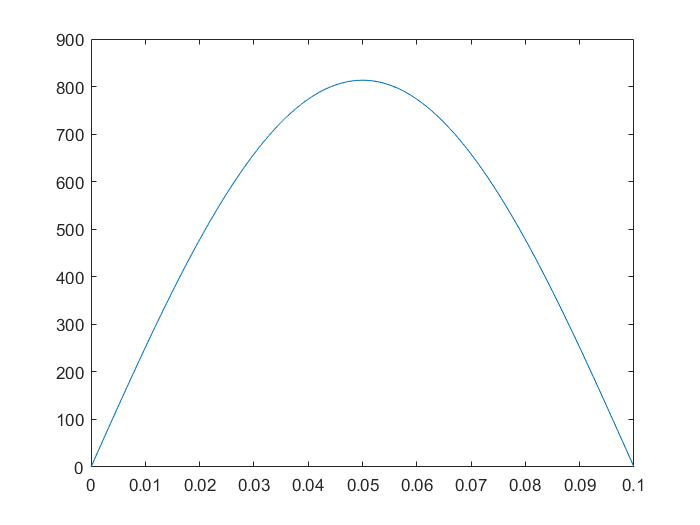

g = 9.81;
m = 33;             % [kg] mass of hip
I = 2.9;            % [kg m^2]
r_1 = 0.4;          % [m] thigh length
r_2 = 0.3;          % [m] shank length
body_length = 0.7;  % [m]

v = 4;

l = 0.4;                            % [m] stride length
T_swing = 0.22;                     % [s] swing time
T_stance = l/v;                     % [s] stance time
T = T_swing + T_stance;             % [s] Total gait time

amp_y = m*g*T*pi()/(4*T_stance);

t = 0:0.001:T_stance;
y = amp_y*sin((pi()/T_stance)*t);
figure;
plot(t,y);

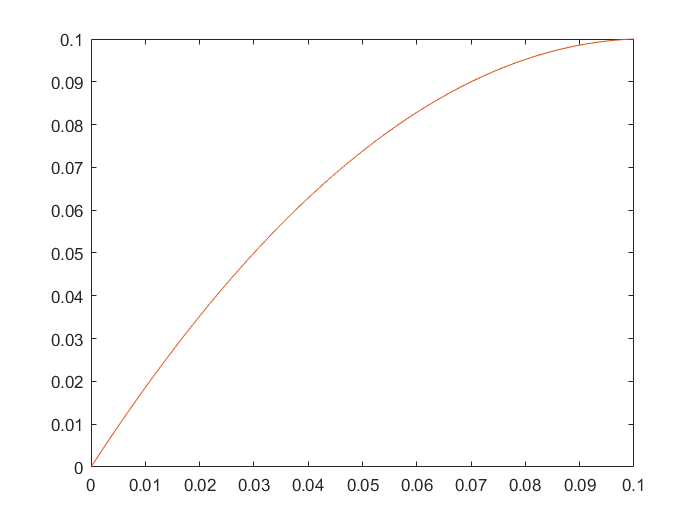


t_new = t + ((0.2)/(T_stance*0.3*0.7)).*t.*(T_stance-t);
t_comp = -(0.2/(0.21*T_stance))*(t.^2) + ((0.5+(0.018/0.21))/0.3)*t;
figure;
plot(t,t_new);
hold on;
plot(t,t_comp)

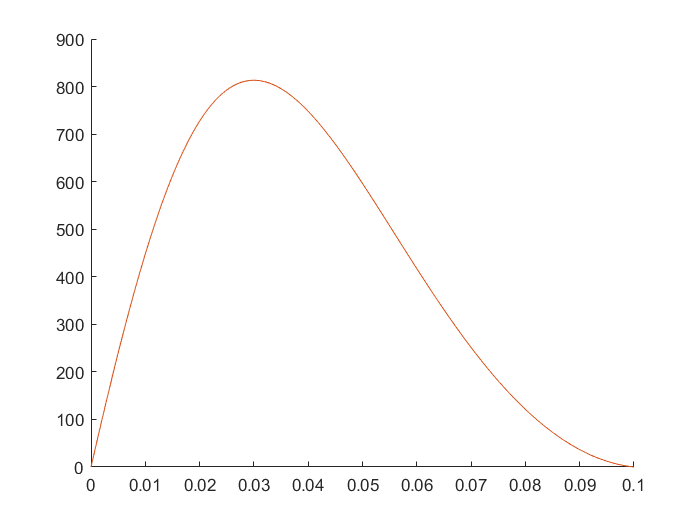


y = amp_y*sin((pi()/T_stance)*t_new);
y_comp = amp_y*sin((pi()/T_stance)*t_comp);
figure;
hold on;
plot(t,y);
plot(t,y_comp)